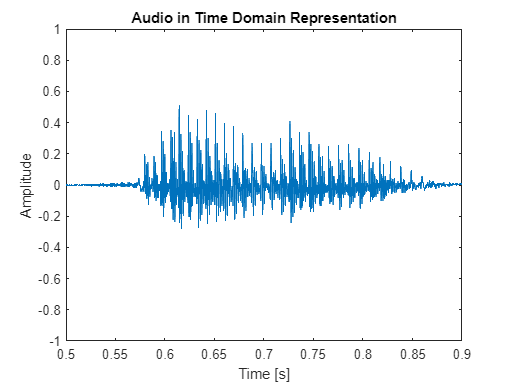

ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_1","IncludeSubfolders",'1');
ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_2","IncludeSubfolders",'2');
ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_3","IncludeSubfolders",'3');
ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_4","IncludeSubfolders",'4');
ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_5","IncludeSubfolders",'5');
ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_6","IncludeSubfolders",'6');
ads = audioDatastore("C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_7","IncludeSubfolders",'7');

% obtain audio time-domain representation
audio_start = 1;
audio_end = numel(audioIn);

% output time-domain plot
audio_start_time_cut = 0.5;
audio_end_time_cut = 0.90;
audio_start_frame_cut = int32(audio_start_time_cut*fs);
audio_end_frame_cut = int32(audio_end_time_cut*fs);

audio_cut = audioIn(audio_start_frame_cut:audio_end_frame_cut);

timeVector = linspace(audio_start_time_cut, audio_end_time_cut, numel(audio_cut));

figure
plot(timeVector, audio_cut)
axis([(audio_start_time_cut) (audio_end_time_cut) -1 1])
ylabel("Amplitude")
xlabel("Time [s]")
title("Audio in Time Domain Representation")

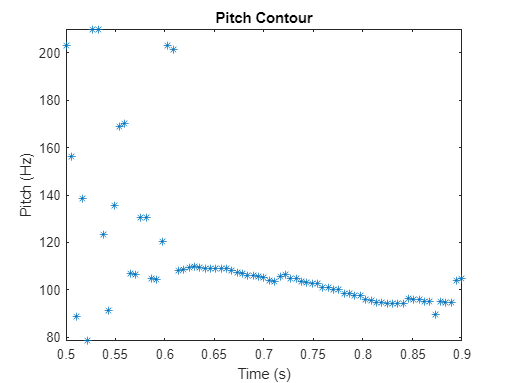


% output sound
%sound(audio_cut,fs);


% acquire pitch
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);

f0 = pitch(audio_cut,fs,WindowLength=windowLength,OverlapLength=overlapLength,Range=[50,250]);

figure
timeVectorPitch = linspace(audio_start_time_cut, audio_end_time_cut, numel(f0));
plot(timeVectorPitch, f0,"*")
axis([(audio_start_time_cut) (audio_end_time_cut) min(f0) max(f0)])
ylabel("Pitch (Hz)")
xlabel("Time (s)")
title("Pitch Contour")

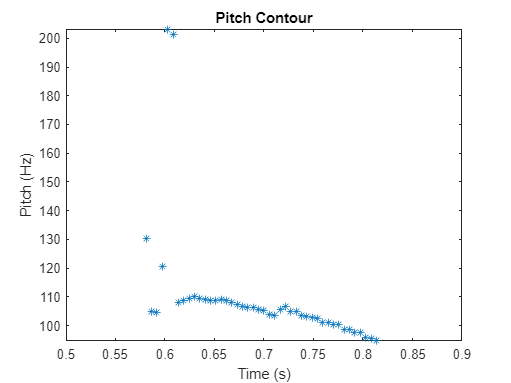


% remove unvoiced speech portion of audio
energyThreshold = 2;        % must decrease this value from 20
[segments,~] = buffer(audio_cut, windowLength, overlapLength, "nodelay");
ste = sum((segments.*hamming(windowLength, "periodic")).^2,1);
isSpeech = ste(:) > energyThreshold;

zcrThreshold = 0.5;         % must increase this value from 0.02
zcr = zerocrossrate(audio_cut, WindowLength=windowLength, OverlapLength=overlapLength);
isVoiced = zcr < zcrThreshold;

voicedSpeech = isSpeech & isVoiced;

% finding the unique different impacts when changing energy threshold or zcr threshold
% finding causes of scattered pitch values during unvoiced speech portions of audio -> change energy or zcr threshold

f0(~voicedSpeech) = NaN;

figure
plot(timeVectorPitch, f0, "*")
axis([(audio_start_time_cut) (audio_end_time_cut) min(f0) max(f0)])
ylabel("Pitch (Hz)")
xlabel("Time (s)")
title("Pitch Contour")


% download data sets
downloadFolder = matlab.internal.examples.downloadSupportFile("audio","commonvoice.zip")

downloadFolder = 'C:\Users\jason\Documents\MATLAB\Examples\R2022a\supportfiles\audio\commonvoice.zip'

dataFolder = "C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM\audio_temp_dir";
% if ~datasetExists(string(dataFolder) + "commonvoice")
%     unzip(downloadFolder,dataFolder);
% end




% matlabroot
% dataFolder = "C:\Users\jason\Desktop\Personal_Projects\Speech_Recognition\MATLAB_MFCC_HMM";
% ads = audioDatastore(fullfile(dataFolder, "dataset"), 'LabelSource','foldernames')
% [adsTrain, adsTest] = splitEachLabel(ads, 0.8);
% adsTrain
% adsTest
% 
% trainDatastoreCount = countEachLabel(adsTrain)


% extract MFCCs
% [coeffs, delta, deltaDelta, loc] = mfcc(audio_cut, fs);
% mfcc(audio_cut, fs);
